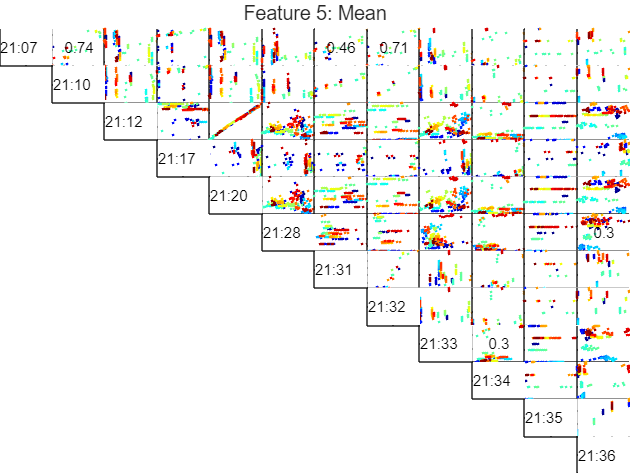

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
selectedFeature = 5; % Mean
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.74  0.29  0.17  0.29  0.01  0.46  0.71  0.03  0.00  0.00  0.00
0.00  0.00  0.18  0.14  0.18  0.00  0.81  1.00  0.00  0.04  0.00  0.01
0.00  0.00  0.00  0.10  1.00  0.04  0.02  0.17  0.15  0.00  0.17  0.12
0.00  0.00  0.00  0.00  0.09  0.12  0.09  0.14  0.01  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.05  0.02  0.17  0.15  0.00  0.16  0.12
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.05  0.29  0.30
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.03  0.10  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.05  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.30  0.12  0.06
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.91
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row 1
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectFeatures(selectedFeature, selectedSignal, featureArray, R2, upperR2, lowerR2);
disp(selectedSignalArray);

     1     2     7     8



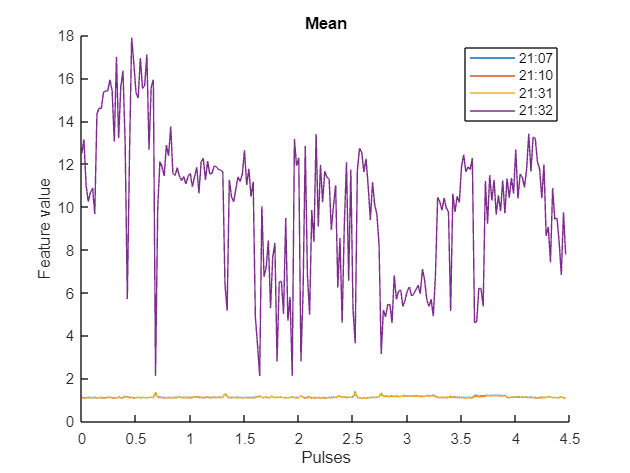

n = size(selectedSignalData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(t, selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

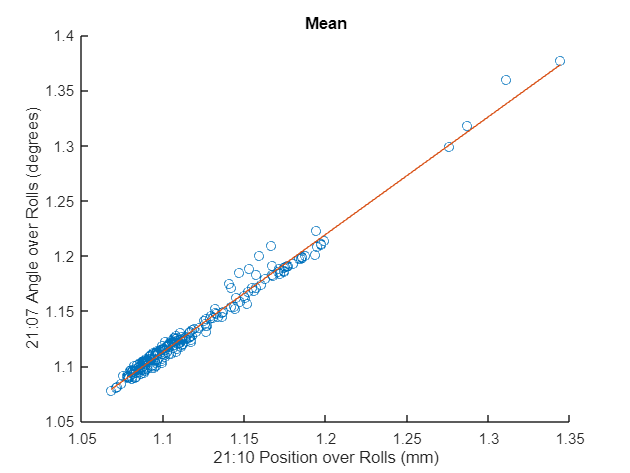

FIT = 87.21

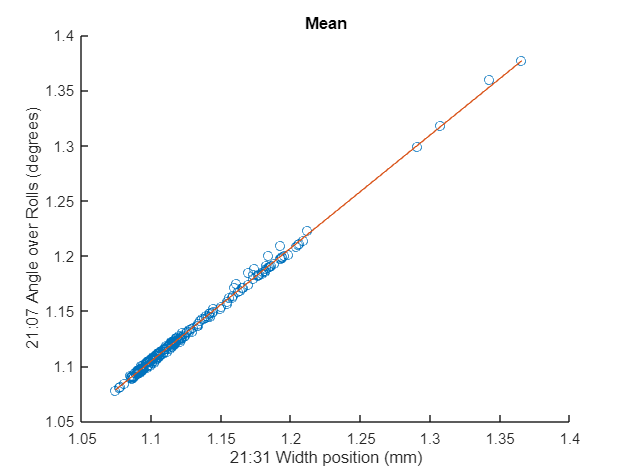

FIT = 94.95

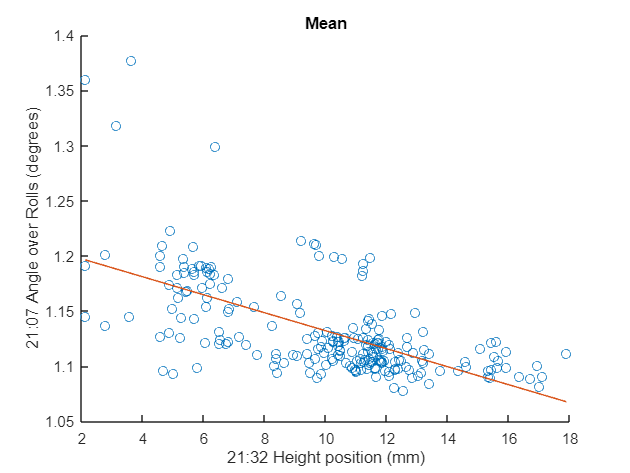

FIT = 21.46

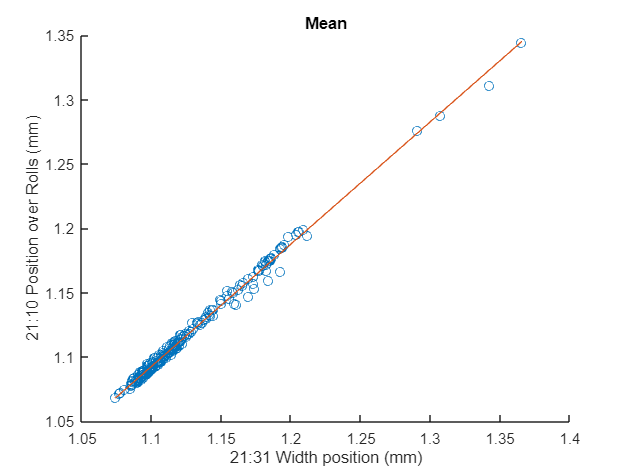

FIT = 92.21

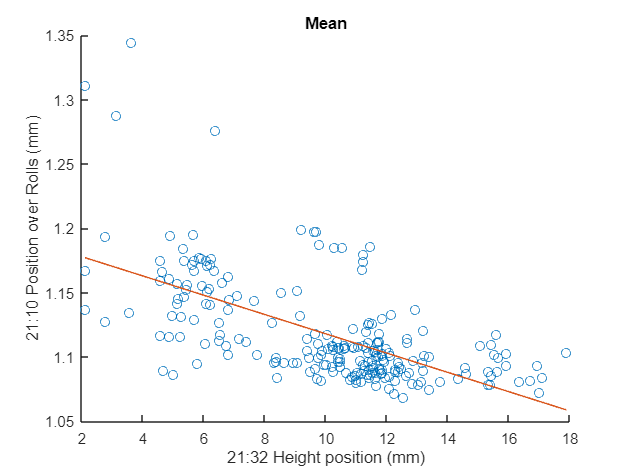

FIT = 20.93

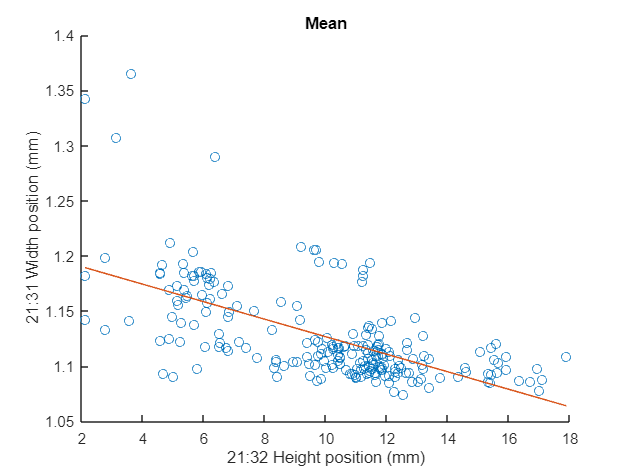

FIT = 21.43

for index1 = 1 : numOfSelectedSignals
    for index2 = index1 + 1 : numOfSelectedSignals
        fnPlotModel(selectedSignalData{index1}, ...
            selectedSignalData{index2}, ...
            FeatureNames(selectedFeature), ...
            sensorNames(selectedSignalArray(index1)), ...
            sensorNames(selectedSignalArray(index2)));
    end
end

1 2 3

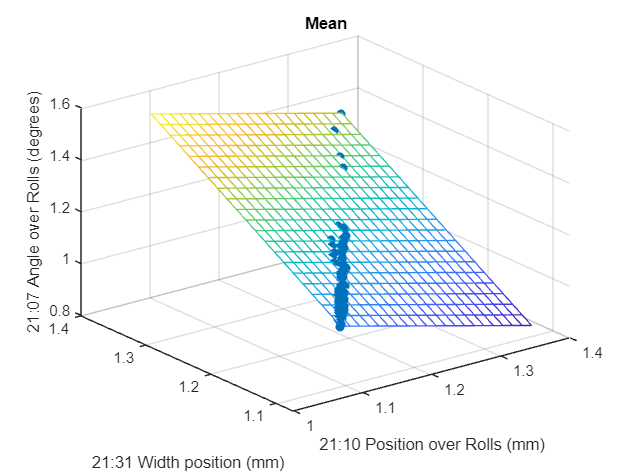

FIT = 99.403682

1 2 4

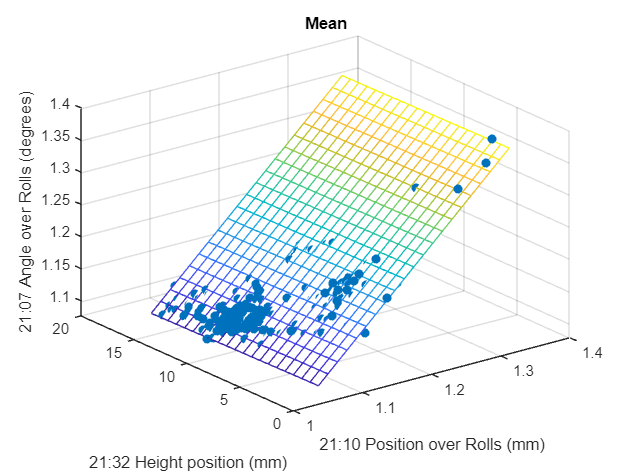

FIT = 87.295313

1 3 4

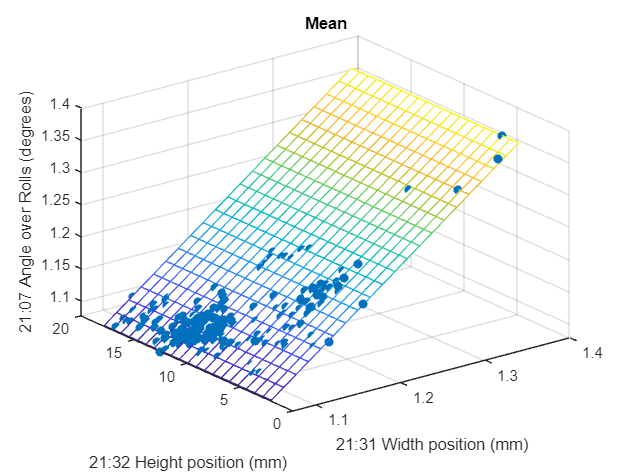

FIT = 94.952416

if numOfSelectedSignals > 2
    for index1 = 2 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            fprintf("%i %i %i", 1, index1, index2);
            Y_est = fnPlotModel3D( ...
                selectedSignalData{1}, ...
                selectedSignalData{index1}, ...
                selectedSignalData{index2}, ...
                FeatureNames(selectedFeature), ...
                sensorNames(selectedSignalArray(1)), ...
                sensorNames(selectedSignalArray(index1)), ...
                sensorNames(selectedSignalArray(index2)));
        end
    end
end